# Calculos Campo

% Campo magnetico
r =6% radio

r = 6

I =40% corriente

I = 40

h =20% altura

h = 20

N =1% num. espriras

N = 1

g = 9.81; % gravedad
M0 = 4*pi*10^-7; % permeabilidad del aire (miu)
masa = 2; % toneladas

tmax = sqrt((2*h)/g);
paso = 0.01; %  paso 
t=0:paso:tmax; % rango en el tiempo
% yi = 0; %ayuda
vel = t.*g% velocidad por segundo

vel =          0    0.0981    0.1962    0.2943    0.3924    0.4905    0.5886    0.6867    0.7848    0.8829    0.9810    1.0791    1.1772    1.2753    1.3734    1.4715    1.5696    1.6677    1.7658    1.8639    1.9620    2.0601    2.1582    2.2563    2.3544    2.4525    2.5506    2.6487    2.7468    2.8449    2.9430    3.0411    3.1392    3.2373    3.3354    3.4335    3.5316    3.6297    3.7278    3.8259    3.9240    4.0221    4.1202    4.2183    4.3164    4.4145    4.5126    4.6107    4.7088    4.8069



% Calculo Campo
%[z,B]=Calculo_campo(paso,t,h,g,M0,I,r) % llamada de la funcion
z = @(t) h + vel .* t + (0.5.*-g.*t.^2);% Posicion en z
B = @(z) (M0*I*r.^2)./(2*(r.^2+z.^2).^(3/2)); %Campo
vel = @(t) t.*g

vel = function_handle with value:
    @(t)t.*g



z1 = z(t)

z1 =    20.0000   20.0005   20.0020   20.0044   20.0078   20.0123   20.0177   20.0240   20.0314   20.0397   20.0490   20.0594   20.0706   20.0829   20.0961   20.1104   20.1256   20.1418   20.1589   20.1771   20.1962   20.2163   20.2374   20.2595   20.2825   20.3066   20.3316   20.3576   20.3846   20.4125   20.4414   20.4714   20.5023   20.5342   20.5670   20.6009   20.6357   20.6715   20.7083   20.7461   20.7848   20.8245   20.8652   20.9069   20.9496   20.9933   21.0379   21.0835   21.1301   21.1777


b1 = B(z1)

b1 = 	1.0e+-7 *

    0.9938    0.9938    0.9936    0.9932    0.9928    0.9922    0.9914    0.9906    0.9895    0.9884    0.9872    0.9858    0.9842    0.9826    0.9808    0.9789    0.9768    0.9747    0.9724    0.9700    0.9675    0.9648    0.9620    0.9592    0.9562    0.9530    0.9498    0.9465    0.9430    0.9394    0.9358    0.9320    0.9281    0.9241    0.9201    0.9159    0.9116    0.9073    0.9028    0.8983    0.8936    0.8889    0.8841    0.8793    0.8743    0.8693    0.8642    0.8590    0.8537    0.8484


V = vel(t)

V =          0    0.0981    0.1962    0.2943    0.3924    0.4905    0.5886    0.6867    0.7848    0.8829    0.9810    1.0791    1.1772    1.2753    1.3734    1.4715    1.5696    1.6677    1.7658    1.8639    1.9620    2.0601    2.1582    2.2563    2.3544    2.4525    2.5506    2.6487    2.7468    2.8449    2.9430    3.0411    3.1392    3.2373    3.3354    3.4335    3.5316    3.6297    3.7278    3.8259    3.9240    4.0221    4.1202    4.2183    4.3164    4.4145    4.5126    4.6107    4.7088    4.8069


A = 2.*pi.*r;

fem = @(t) vel(t).*B(z(t)).*A

fem = function_handle with value:
    @(t)vel(t).*B(z(t)).*A


FEM = fem(t)

FEM = 	1.0e+-4 *

         0    0.0037    0.0073    0.0110    0.0147    0.0183    0.0220    0.0256    0.0293    0.0329    0.0365    0.0401    0.0437    0.0472    0.0508    0.0543    0.0578    0.0613    0.0647    0.0682    0.0716    0.0749    0.0783    0.0816    0.0849    0.0881    0.0913    0.0945    0.0976    0.1008    0.1038    0.1069    0.1098    0.1128    0.1157    0.1186    0.1214    0.1241    0.1269    0.1296    0.1322    0.1348    0.1373    0.1398    0.1423    0.1447    0.1470    0.1493    0.1516    0.1537


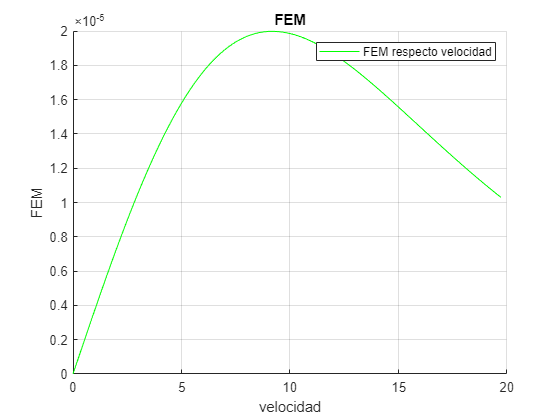


% Grafica fem respecto al tiempo
clf;
hold on
plot(t,FEM,'b')
title("FEM")
legend("FEM respecto tiempo")
xlabel("tiempo")
ylabel("FEM")
grid on
hold off

% Grafica fem respecto a la posicion
clf;
hold on
plot(z1,FEM,'m')
title("FEM")
legend("FEM respecto posicion")
xlabel("posicion")
ylabel("FEM")
grid on
hold off

% Grafica la fem respecto a la Velocidad 
clf;
hold on
plot(V,FEM,'g')
title("FEM")
legend("FEM respecto velocidad")
xlabel("velocidad")
ylabel("FEM")
grid on
hold off

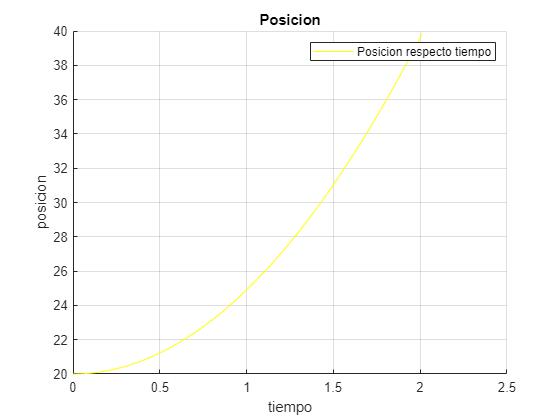


% Grafica la Posicion respecto al tiempo 
clf;
hold on
plot(t,z1,'y')
title("Posicion")
legend("Posicion respecto tiempo")
xlabel("tiempo")
ylabel("posicion")
grid on
hold off


% Flujo del campo magnetico
% A = pi*r^2; %Superficie
% vel = % velocidad por segundo
% fi = (M0.*N.*I./z).*A; %Flujo magnetico
% fi = B.*A %Flujo 
% Integrar 
% plot(z,fi,'*b');
% plot(t,fi,'-m-);
% grid on


% fem instantanea, B*A (sin velocidad por que es el punto 0; instantanea)